clear all
close all

## Modulating Signal

m = 1

m = 1


Vm = 20

Vm = 20

fm = 150000

fm = 150000

Tm = 1/fm

Tm = 6.6667e-06

t = 0:Tm/999:6*Tm

t = 	1.0e+-4 *

         0    0.0001    0.0001    0.0002    0.0003    0.0003    0.0004    0.0005    0.0005    0.0006    0.0007    0.0007    0.0008    0.0009    0.0009    0.0010    0.0011    0.0011    0.0012    0.0013    0.0013    0.0014    0.0015    0.0015    0.0016    0.0017    0.0017    0.0018    0.0019    0.0019    0.0020    0.0021    0.0021    0.0022    0.0023    0.0023    0.0024    0.0025    0.0025    0.0026    0.0027    0.0027    0.0028    0.0029    0.0029    0.0030    0.0031    0.0031    0.0032    0.0033


vm = Vm*sin(2*pi*fm*t)

vm =          0    0.1258    0.2516    0.3773    0.5031    0.6288    0.7546    0.8802    1.0059    1.1315    1.2571    1.3826    1.5080    1.6334    1.7588    1.8840    2.0092    2.1343    2.2594    2.3843    2.5092    2.6339    2.7585    2.8831    3.0075    3.1318    3.2560    3.3800    3.5039    3.6277    3.7513    3.8748    3.9981    4.1213    4.2443    4.3672    4.4898    4.6123    4.7346    4.8567    4.9787    5.1004    5.2219    5.3433    5.4644    5.5853    5.7059    5.8264    5.9466    6.0666


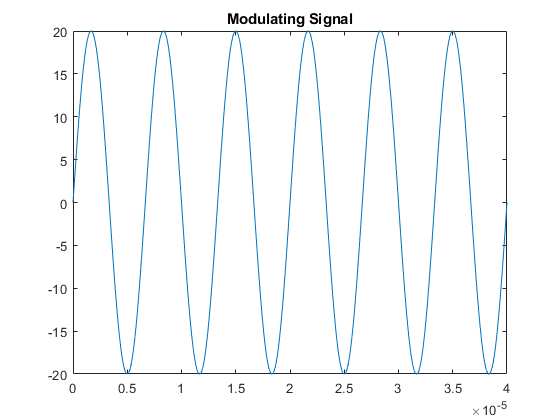

% figure(1);
% subplot(3,1,1);
figure(1);
plot(t,vm);
title('Modulating Signal')


%gaussiannoise=awgn(voice_message_signal,25)
%figure(100);
%sound(gaussiannoise,Fs)
%plot(1:minLength,gaussiannoise)
%title('Gaussian Noise')

## Carrier Signal

Vc=Vm/m

Vc = 20

fc = 10000000

fc = 10000000

Tc = 1/fc

Tc = 1.0000e-07

vc = Vc*sin(2*pi*fc*t)

vc =          0    8.1424   14.8741   19.0289   19.8869   17.2995   11.7150    4.1008   -4.2238  -11.8167  -17.3623  -19.8999  -18.9898  -14.7897   -8.0273    0.1258    8.2571   14.9579   19.0672   19.8732   17.2360   11.6128    3.9776   -4.3467  -11.9179  -17.4244  -19.9120  -18.9499  -14.7048   -7.9120    0.2516    8.3715   15.0411   19.1048   19.8586   17.1719   11.5101    3.8542   -4.4694  -12.0187  -17.4858  -19.9234  -18.9093  -14.6192   -7.7963    0.3773    8.4856   15.1237   19.1417   19.8433


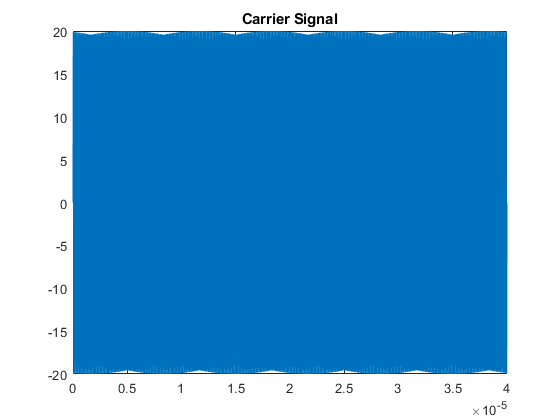

% figure(1);
% subplot(3,1,2);
figure(2);
plot(t,vc)
title('Carrier Signal')

## Amplitude Modulation

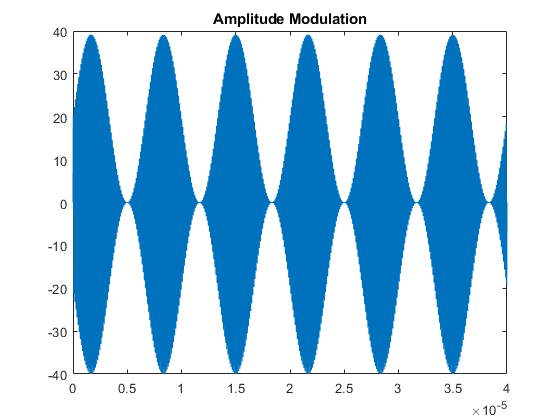

Am = (Vc+Vm*sin(2*pi*fm*t)).* sin(2*pi*fc*t);
% subplot(3,1,3);

figure(3);
plot(t,Am);
title('Amplitude Modulation')

## Project Proper  Amplitude Modulation

## Modulated Signal

%Read the audio signal [Modulating Signal]
[voice_message_signal, Fs] = audioread('C:\1 Partition\EJ\SCHOOL\ECE2\TERM 7\COMMANA\final proj\commana_proj-main\commana_proj-main\epic_voice.wav')

voice_message_signal =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


Fs = 48000

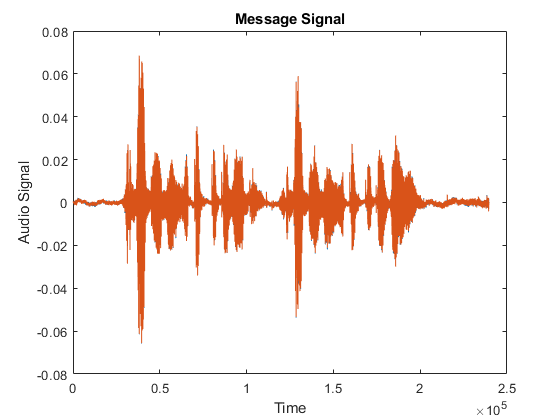

sound(voice_message_signal,Fs)
%sound(y, Fs)
figure(4); plot(voice_message_signal)
shg
xlabel 'Time'
ylabel 'Audio Signal'
title('Message Signal')

## Carrier Signal

Vc =Vm/m

Vc = 20

fc = 10000000

fc = 10000000

Tc = 1/fc

Tc = 1.0000e-07

n = 0:Tm/999:300*Tm

n =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


vc = Vc*sin(2*pi*fc*n)

vc =          0    8.1424   14.8741   19.0289   19.8869   17.2995   11.7150    4.1008   -4.2238  -11.8167  -17.3623  -19.8999  -18.9898  -14.7897   -8.0273    0.1258    8.2571   14.9579   19.0672   19.8732   17.2360   11.6128    3.9776   -4.3467  -11.9179  -17.4244  -19.9120  -18.9499  -14.7048   -7.9120    0.2516    8.3715   15.0411   19.1048   19.8586   17.1719   11.5101    3.8542   -4.4694  -12.0187  -17.4858  -19.9234  -18.9093  -14.6192   -7.7963    0.3773    8.4856   15.1237   19.1417   19.8433


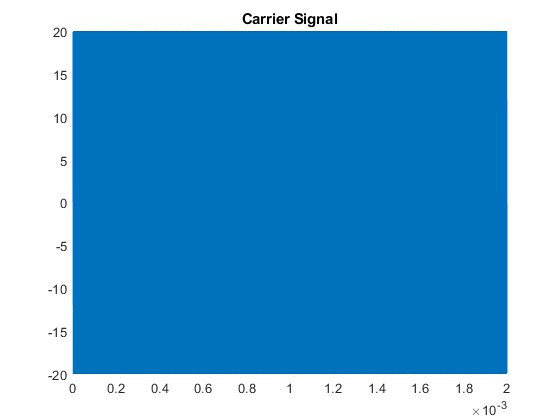

% figure(1);
% subplot(3,1,2);
figure(2);
plot(n,vc)
title('Carrier Signal')

## Length Adjustment

carrier_signal = vc

carrier_signal =          0    8.1424   14.8741   19.0289   19.8869   17.2995   11.7150    4.1008   -4.2238  -11.8167  -17.3623  -19.8999  -18.9898  -14.7897   -8.0273    0.1258    8.2571   14.9579   19.0672   19.8732   17.2360   11.6128    3.9776   -4.3467  -11.9179  -17.4244  -19.9120  -18.9499  -14.7048   -7.9120    0.2516    8.3715   15.0411   19.1048   19.8586   17.1719   11.5101    3.8542   -4.4694  -12.0187  -17.4858  -19.9234  -18.9093  -14.6192   -7.7963    0.3773    8.4856   15.1237   19.1417   19.8433



minLength = min(length(voice_message_signal), length(vc))

minLength = 239616

%minLength = minLength/2
voice_message_signal = voice_message_signal(1:minLength)

voice_message_signal =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000         0         0         0         0         0    0.0000    0.0000    0.0000         0         0         0         0   -0.0000         0    0.0001    0.0000    0.0000    0.0000    0.0000


vc = vc(1:minLength)

vc =          0    8.1424   14.8741   19.0289   19.8869   17.2995   11.7150    4.1008   -4.2238  -11.8167  -17.3623  -19.8999  -18.9898  -14.7897   -8.0273    0.1258    8.2571   14.9579   19.0672   19.8732   17.2360   11.6128    3.9776   -4.3467  -11.9179  -17.4244  -19.9120  -18.9499  -14.7048   -7.9120    0.2516    8.3715   15.0411   19.1048   19.8586   17.1719   11.5101    3.8542   -4.4694  -12.0187  -17.4858  -19.9234  -18.9093  -14.6192   -7.7963    0.3773    8.4856   15.1237   19.1417   19.8433


## Voice Modulated Signal

Voice_Modulated_Signal = voice_message_signal .* vc

Voice_Modulated_Signal =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000         0         0         0         0         0    0.0004    0.0001   -0.0001         0         0         0         0    0.0004         0    0.0000    0.0003    0.0005    0.0006    0.0006


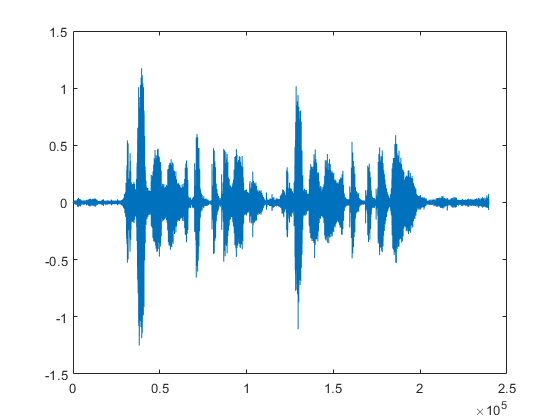


sound(voice_message_signal,Fs)
sound(Voice_Modulated_Signal,Fs)
% Voice_Modulated_Signal = (Vc+voice_message_signal) .* sin(2*pi*fc*t)
figure(5);
plot(1:minLength,Voice_Modulated_Signal)

## **Gaussian Noise**

%Read the audio signal [Modulating Signal]
[voice_message_signal, Fs] = audioread('C:\1 Partition\EJ\SCHOOL\ECE2\TERM 7\COMMANA\final proj\commana_proj-main\commana_proj-main\epic_voice.wav')

voice_message_signal =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


Fs = 48000

%sound(voice_message_signal,Fs)
%sound(y, Fs)
voice_message_signal=voice_message_signal(:,1:1)

voice_message_signal =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


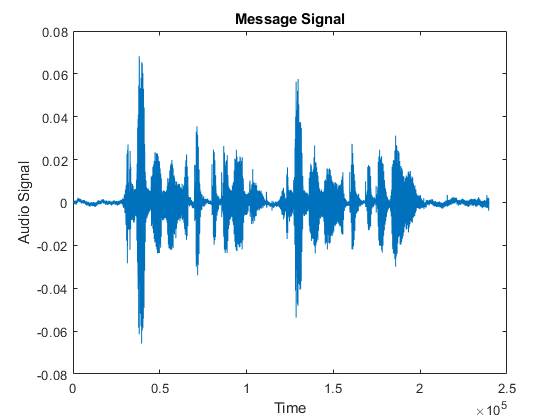

figure(99); plot(voice_message_signal)
shg
xlabel 'Time'
ylabel 'Audio Signal'
title('Message Signal')


gaussiannoise=awgn(voice_message_signal,53)

gaussiannoise =     0.0006
    0.0024
    0.0025
   -0.0021
   -0.0003
   -0.0045
   -0.0000
   -0.0026
   -0.0014
   -0.0000


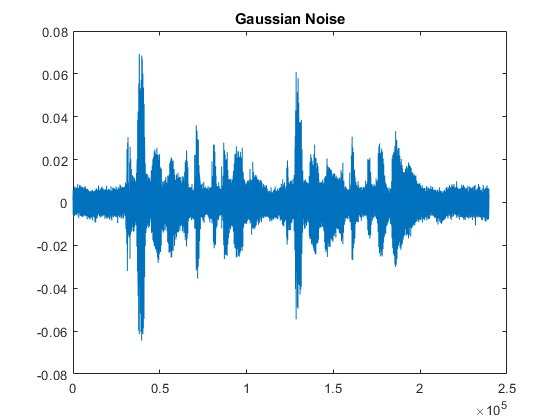

figure(100);
sound(gaussiannoise,Fs)
plot(1:minLength,gaussiannoise)
title('Gaussian Noise')